clear all; close all;

## Load data

load("Observations_nb.mat");                      % load data
fs = 10000 ;                                      % sample rate (Hz)

## Plot waveform

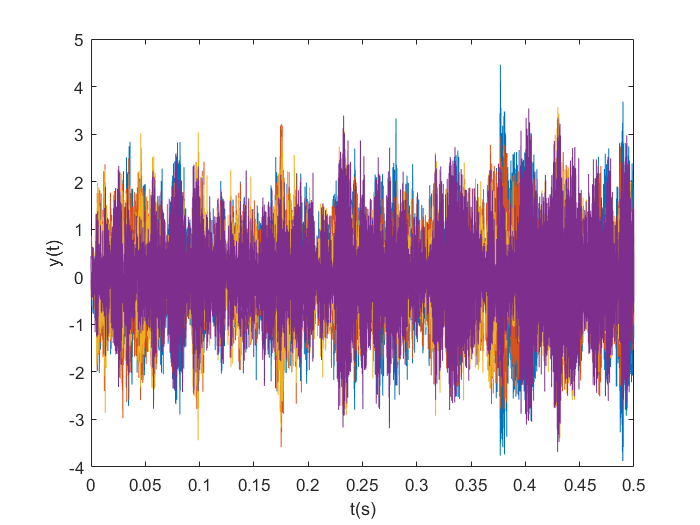

dt = 1 / fs;
t = 0:dt:0.5-dt;
y = X;
N = length(X);
f = (-N/2:N/2-1)*fs/N;
Y = fftshift(fft(y))/N;
plot(t,y); xlabel('t(s)');ylabel('y(t)')

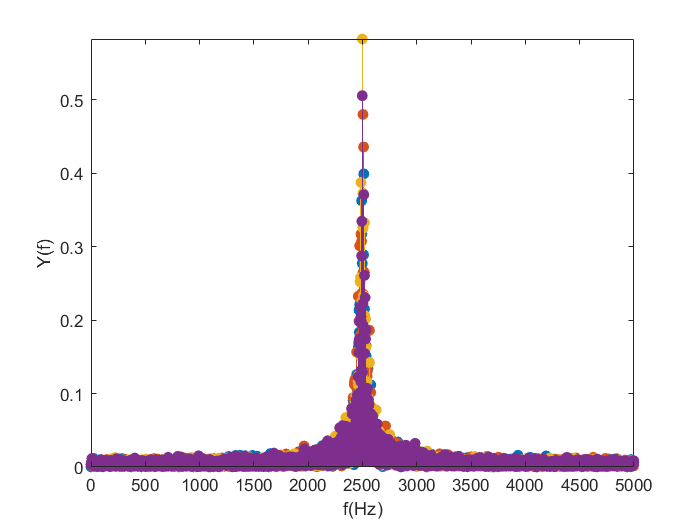

figure;
stem(f,abs(Y),'filled');axis([0 5000 0 inf]);
xlabel('f(Hz)');ylabel('Y(f)')

## Array setup

[Frame,nSensors] = size(X);                            
J = nSensors;                                      % number of sensors
dx = 0.034;                                        % inter-sensor distance in x direction (m)
dy = 0;                                            % sensor distance in y direction (m)
c = 340;                                           % sound velocity  (m)
n_source = 2;                                      % number of sources
Index = linspace(0,J-1,J);
p = (-(J-1)/2 + Index.') * [dx dy];                % sensor position

## Plot sensor positions

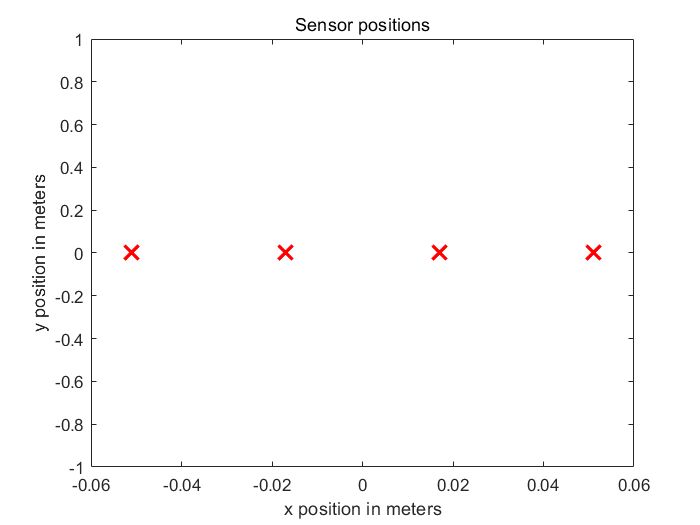

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure
plot(p(:,1),p(:,2),linspec{:});  
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The four microphones are ready !');

The four microphones are ready !


## DoA estimation (MUSIC)

stride = 1;                                            % determine the angular resolution(deg)
theta = -90:stride:90;                                 % grid
f_c = 2500;                                            % center frequency  (Hz)
A=X(:,1);B=X(:,2);C=X(:,3);D=X(:,4);
r=[0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0];
for i=1:5000
    NE=[complex(A(i,1)),complex(B(i,1)),complex(C(i,1)),complex(D(i,1))];
    r1=NE'*NE;
    r=r+r1;
end
R_x = r/5000;                                          % autocorrelation estimate
v = [sin(theta*pi/180);-cos(theta*pi/180)];            % direction vector  
a_theta = exp(-1j*2*pi*f_c*(p*v)./c);                  % steer vector                                                       
[q,w]=eig(R_x);                                        % implement eigen-decomposition 
Un  = [q(:,1),q(:,2)];                                 % noise subspace (columns are eigenvectors), size: J*(J-n_source)
P_sm = 1./diag(a_theta'*(Un*Un')*a_theta);             % pseudo music power

## Plot the MUSIC pseudo power spectrum

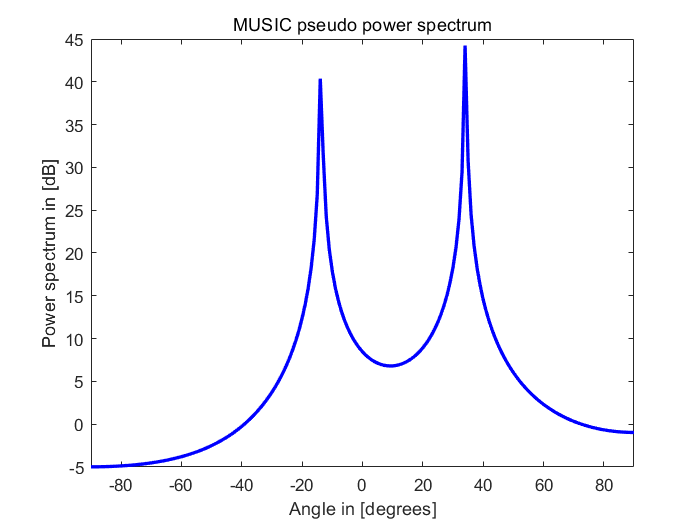

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:})
title('MUSIC pseudo power spectrum')
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

## Find the local maximum and visualization

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -14 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 34 deg
